dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
dcmImgs = dcmHandler.readAllImage();
[dcminfo, dcmimg] = dcmHandler.getPreview();
dcminfo.Rows

ans = uint16
384

dcminfo.Columns

ans = uint16
384

ans = 'scripts.imageViewer.gradationProcessor'

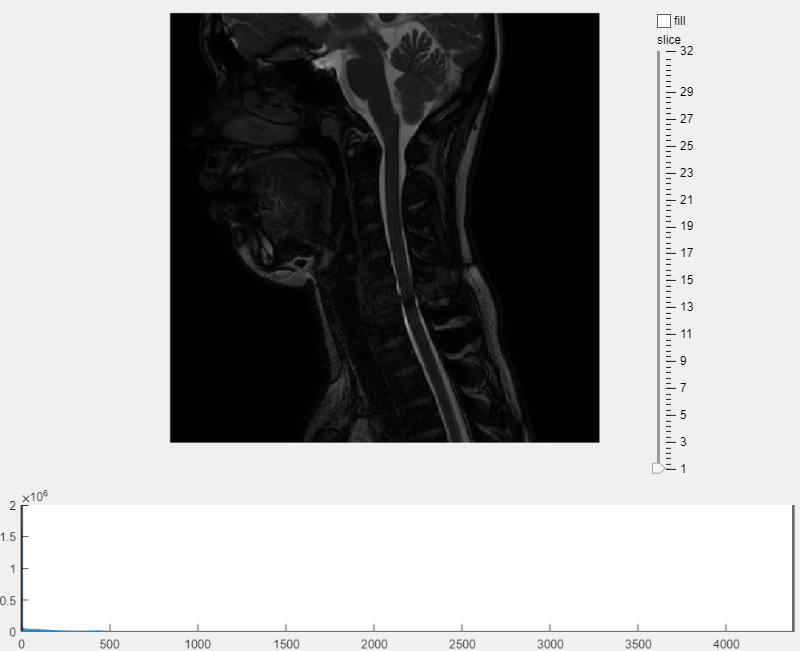


imViewer = scripts.imageViewer.guiImageViewer("image3D", dcmImgs, "imageWidth", dcminfo.Rows, "imageHeight", dcminfo.Columns);

% optFlowLK = opticalFlowLK("NoiseThreshold", 0.1);
% inputSize = size(dcmImgs);
% opticalFlowImg = zeros(inputSize);
% cmap = colormap('jet');
% F = zeros(inputSize(3));

% for i = 1:inputSize(3)
%     flow = estimateFlow(optFlowLK, dcmImgs(:,:,i));
%     opticalFlowImg(:,:,i) = flow.Magnitude;
%     F(i) = im2frame(opticalFlowImg(:,:,i), cmap);
% 
% end


            

% test = scripts.imageViewer.guiImageViewer("image3D", dcmImgs)